# INTERPOLACIÓ POLINOMIAL (segona part)

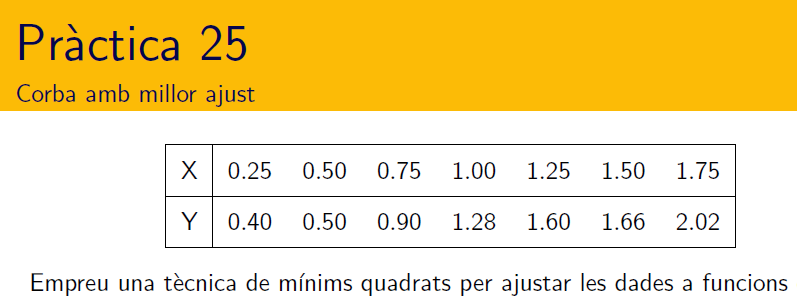

x = [0.25 0.50 0.75 1 1.25 1.50 1.75]

x =          0.25          0.5         0.75            1         1.25          1.5         1.75


y = [0.40 0.50 0.90 1.28 1.60 1.66 2.02]

y =           0.4          0.5          0.9         1.28          1.6         1.66         2.02


unos = ones(size(x));

- **Exercici 1**

 Ajusteu les dades a una recta $y = a_0+a_1x$, es a dir determineu $a_0 $ i $a_1$, doneu l'equació obtinguda i calculeu el vector residu

A = [x' unos']

A =          0.25            1
          0.5            1
         0.75            1
            1            1
         1.25            1
          1.5            1
         1.75            1


b = y'

b =           0.4
          0.5
          0.9
         1.28
          1.6
         1.66
         2.02


[l] = minimos_cuadrados(A,b)

l =        1.1257
     0.068571


**RESPOSTA:  **l'equació de la recta és  

- **Exercici 2**

Ajusteu les dades a una paràbola $y = a_0+a_1x+a_2x^2$, es a dir determineu $a_0 ,\ a_1$ i $a_2$, doneu l'equació obtinguda i calculeu el vector residu

A = [x'.^2 x' unos']

A =        0.0625         0.25            1
         0.25          0.5            1
       0.5625         0.75            1
            1            1            1
       1.5625         1.25            1
         2.25          1.5            1
       3.0625         1.75            1


b = y'

b =           0.4
          0.5
          0.9
         1.28
          1.6
         1.66
         2.02


[l] = minimos_cuadrados(A,b)

l =     -0.099048
       1.3238
   -0.0057143


**RESPOSTA:  **l'equació de la parábola és

- **Exercici 3**

Ajusteu les dades a un polinomi de grau 4 $y = a_0+a_1x+a_2x^2+a_3x^3+a_4x^4$, es a dir determineu $a_0 ,\ a_1 ,\ a_2 ,\ a_3$ i $a_4$, doneu l'equació obtinguda i calculeu el vector residu

A = [x'.^4 x'.^3 x'.^2 x' unos']

A =     0.0039063     0.015625       0.0625         0.25            1
       0.0625        0.125         0.25          0.5            1
      0.31641      0.42188       0.5625         0.75            1
            1            1            1            1            1
       2.4414       1.9531       1.5625         1.25            1
       5.0625        3.375         2.25          1.5            1
       9.3789       5.3594       3.0625         1.75            1


b = y'

b =           0.4
          0.5
          0.9
         1.28
          1.6
         1.66
         2.02


[l] = minimos_cuadrados(A,b)

l =        2.2497
      -9.4255
       13.333
      -6.0767
       1.2286


**RESPOSTA:  **l'equació del polinomi és

- **Exercici 4**

Ajusteu les dades a una corba del tipus $y =ax^\alpha$, es a dir determineu $a$ i $\alpha$, doneu l'equació obtinguda i calculeu el vector residu

**RESPOSTA:  **l'equació de la corba és

- **Exercici 5**

Quin del tipus sembla més adient. Per què? Argumenta la teva resposta.

**RESPOSTA:**

- **Exercici 6**

Representeu les dades i les funcions obtingudes en un mateix gràfic

function [x] = minimos_cuadrados(A,b)
    %A'*Ax=A'b
    C = A'*A;
    d = A'*b;
    x = C\d;
end